clc; clear all; close all;
syms s P1 P2 P3 C;

%Transfer function of the plant G
num = [7.4,14,6.7];
den = [1,2.6,10,17,8];
G = tf(num,den)

G =
 
        7.4 s^2 + 14 s + 6.7
  ---------------------------------
  s^4 + 2.6 s^3 + 10 s^2 + 17 s + 8
 
Continuous-time transfer function.
Model Properties



% P gain controllers
P1=1;
P2=4;
P3=100;


## Question a)

Is the transfer function G(s) stable? Please explain briefly how you come to this conclusion

poles = pole(G);  % Get the poles of the transfer function

% Checks stability
if all(real(poles) < 0) 
    disp('The transfer function is stable.');
else
    disp('The transfer function NOT stable.');

end

The transfer function is stable.


## Question b)

 Generate the impulse response of the transfer function G(s) on the time interval [0, 33] s, by utilizing the impulse function in Matlab. Add the resulting plot to the answerform_4.docx document. What happens to the response in the long term? What is the physical significance of this? 

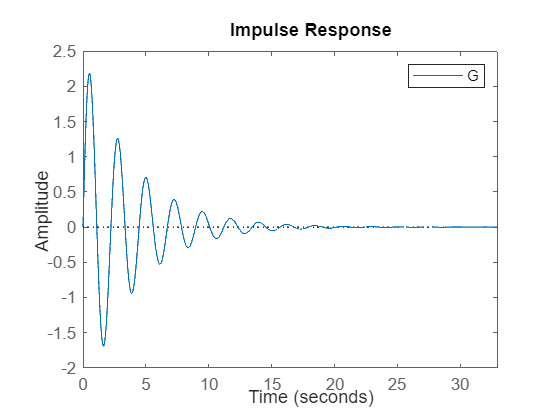

time = 0:0.01:33; % Sets the time interval
impulse(G,time)   % Generates the impulse response plot
legend

## Question c)

Consider a closed-loop interconnection as depicted in Figure 7, where the controller is described by C(s) = P where P is as a constant, and the plant (RWP) is described by the transfer function G(s). Select C(s) = P1, and determine if the closed-loop transfer function between reference r and output y is stable. Please explain how you came to this conclusion. Repeat this for C(s) = P2 and C(s) = P3.

%
C1=P1;
T1=feedback(C1*G,1)    % Creates the new transfer function of the system

T1 =
 
           7.4 s^2 + 14 s + 6.7
  --------------------------------------
  s^4 + 2.6 s^3 + 17.4 s^2 + 31 s + 14.7
 
Continuous-time transfer function.
Model Properties


polesT1=pole(T1)       % Finds the poles

polesT1 =   -0.3014 + 3.8910i
  -0.3014 - 3.8910i
  -1.1774 + 0.0000i
  -0.8197 + 0.0000i


if all(real(poles) < 0)       % Checks for stability
    disp('The transfer function  T1 is stable.');
else
    disp('The transfer function T1 NOT stable.');

end

The transfer function  T1 is stable.



%
C2=P2;
T2=feedback(C2*G,1)

T2 =
 
          29.6 s^2 + 56 s + 26.8
  --------------------------------------
  s^4 + 2.6 s^3 + 39.6 s^2 + 73 s + 34.8
 
Continuous-time transfer function.
Model Properties


polesT2=pole(T2)

polesT2 =   -0.3319 + 6.1052i
  -0.3319 - 6.1052i
  -1.0476 + 0.0000i
  -0.8886 + 0.0000i


if all(real(poles) < 0) 
    disp('The transfer function  T2 is stable.');
else
    disp('The transfer function T2 NOT stable.');

end

The transfer function  T2 is stable.



%
C3=P3;
T3=feedback(C3*G,1)

T3 =
 
          740 s^2 + 1400 s + 670
  --------------------------------------
  s^4 + 2.6 s^3 + 750 s^2 + 1417 s + 678
 
Continuous-time transfer function.
Model Properties


polesT3=pole(T3)

polesT3 =   -0.3529 +27.3429i
  -0.3529 -27.3429i
  -0.9471 + 0.0988i
  -0.9471 - 0.0988i


if all(real(poles) < 0) 
    disp('The transfer function  T3 is stable.');
else
    disp('The transfer function T3 NOT stable.');

end

The transfer function  T3 is stable.


## Question d)

Select C(s) = P1, and generate the step response of the closed-loop transfer function. Utilize the step function in Matlab for this purpose and consider the time interval [0, 24] s. Add the resulting plot to the answerform_4.docx document. Repeat this for C(s) = P2 and C(s) = P3 and give all plots in a single figure. Also, calculate the final value (i.e., in the limit t → ∞) of the response for each case. If there is no final value for any of these cases, explain why. What influence does increasing P have on the final value?

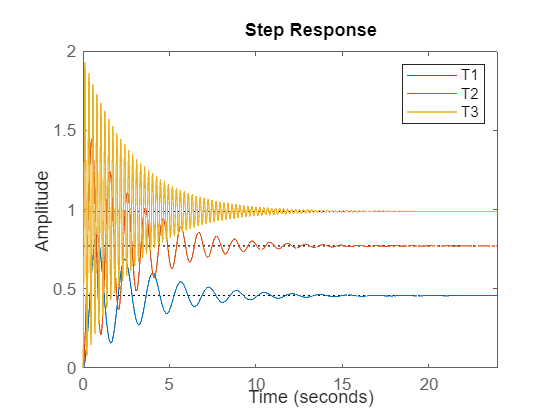

time2=0:0.01:24; % Sets the time interval

% Plots the step response of the closed loop transfer functions
step(T1,time2)
hold on
step(T2,time2)
hold on
step(T3,time2)
legend
hold off

## Question e)

Plot the location of the poles and zeros of the closed-loop transfer function for each case C(s) = P1, C(s) = P2, and C(s) = P3. What is the effect of increasing the gain P? In your answer, make reference to how the position of the poles affect the frequency of oscillation, and settling time (Note: be careful of zeros that may (almost) cancel the effect of poles). Based on your findings (from questions 4d and 4e), explain whether or not you would recommend the use of a (purely) proportional controller C(s) = P for this application. Hint: use the pzmap function in Matlab to plot the location of the poles and zeros. Provide a plot of the pole-zero map where the real axis ranges shows the interval [−1.3, −0.17] and the imaginary axis shows the interval [−30, 30]. Additionally, provide a zoomed in version of this plot where the real axis shows the interval [−0.36, −0.29] and the imaginary axis shows the interval [−30, 30].

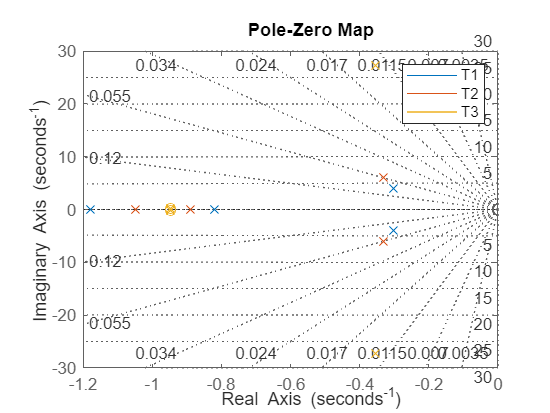

%Plots the location of poles and zeros for the closed loop transfer
%function
pzmap(T1,T2,T3)
grid on
legend

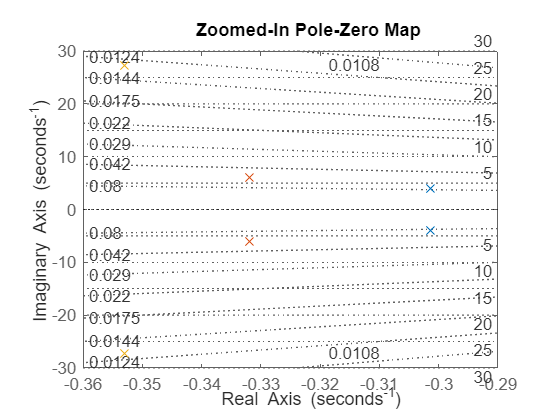


% Zoomed-In Pole-Zero Map
figure;
pzmap(T1,T2,T3)
title('Zoomed-In Pole-Zero Map ');
grid on;
axis([-0.36 -0.29 -30 30]); % Zoomed-in limits

## Question f)

Select a PD controller given by C(s) = 0.31s+3.5. Generate the step response of the closedloop transfer function on the time interval [0, 7.5] s. Also, generate the step response of the closed-loop transfer function with the controller C(s) = P2. Plot both on a single graph.

PD_Controller = tf([0.31, 3.5], 1);  % PD Controller C(s) = 0.31s + 3.5

% Closed-loop Transfer Functions
T_PD = feedback(PD_Controller * G, 1);  % Closed-loop transfer function with PD Controller
T_P2 = feedback(P2 * G, 1);             % Closed-loop transfer function with P2 Controller


time3= 0:0.01:7.5;  % Time interval
step_PD = step(T_PD, time3);  % Step response for PD controller
step_P2 = step(T_P2, time3);  % Step response for P2 controller

% Plot the Step Responses
figure;
plot(time3, step_PD, 'LineWidth', 2); hold on;
plot(time3, step_P2, '--', 'LineWidth', 2);
title('Step Response: PD vs Proportional Controller');
xlabel('Time (seconds)');
ylabel('Response');
legend('PD Controller', 'Proportional Controller');
grid on;


## Question g)

Compare the controllers C(s) = 0.31s+3.5 and C(s) = P2. In your answer, make reference to the final value, frequency of oscillation, and settling time. Also make reference to the closedloop pole locations of both systems (Note: again be careful of zeros that may (almost) cancel the effect of poles). Plot the location of the poles and zeros for both cases on a single graph where the real axis shows the interval [−1.6, −0.16] and the imaginary axis shows the interval [−7, 7].

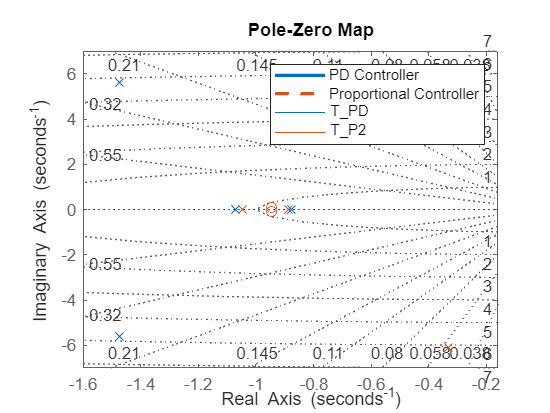

%Plots the location of poles and zeros
pzmap(T_PD,T_P2)
grid on
axis([-1.6 -0.16 -7 7]);

legend